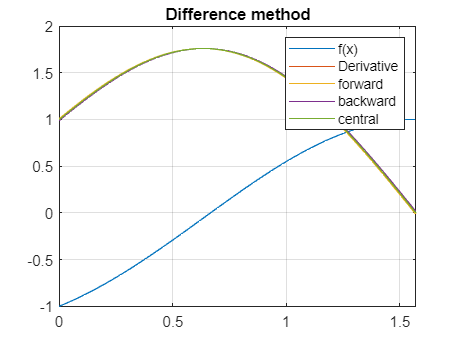

%Numerical differentiation

x=linspace(0,pi/2,100);
f= @(x) sin(x)-cos(x).^2;
y=f(x);
dy_dx= cos(x)+2.*sin(x).*cos(x);

h=0.01;

%forward difference
dy_dxF=(f(x+h)-f(x))/h;

%backward difference
dy_dxB=(f(x)-f(x-h))/h;

%Central difference
dy_dxC=(f(x+h)-f(x-h))/(2*h);

plot(x,y)
hold on
plot(x,dy_dx)
plot(x,dy_dxF)
plot(x,dy_dxB)
plot(x,dy_dxC)
hold off
title('Difference method')
legend('f(x)','Derivative','forward','backward','central')
grid on

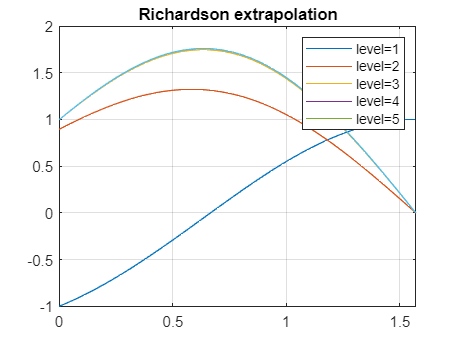

%Richardson extrapolation

n=100;
x=linspace(0,pi/2,n);
f= @(x) sin(x)-cos(x).^2;
y=f(x);
h=0.8;
levels=5;
Richardson_derivatives_matrix=ones(levels,n);
for i=1:levels
    Richardson_derivatives_matrix(i,:)=[Richardson_extrapolation(f,x,h,i)]';
end

plot(x,y)
hold on
for i=1:levels
    plot(x,Richardson_derivatives_matrix(i,:))
end
hold off
title('Richardson extrapolation')
legendCell = strcat('level=',string(num2cell(1:levels)));
legend(legendCell);
grid on

function diff=Richardson_extrapolation(f,x,h,n)
    if n==1
        diff=(f(x+h)-f(x-h))/(2*h);
    else
        diff = (4^(n-1)*Richardson_extrapolation(f,x,h/2,n-1)-Richardson_extrapolation(f,x,h,n-1))/(4^(n-1)-1);
    end
end